# Bridge of Doom

## Excercise 21.1

% plot the theoretical curve of the Bridge of Doom
clf
clear all
hold on

% set the step size
h = 3.2/300;

% set the u-values
u = (0:h:3.2);

% create the postition vector r for the Bridge of Doom
x = 4.*(0.3960.*cos(2.65.*(u + 1.4)));
y = 4.*-0.99.*sin(u + 1.4);

% Plot the theoretical path of the Bridge of Doom
plot(x, y, 'k')
title('Bridge of Doom Curve with Tangent and Normal Vectors')
xlabel('Distance (m)')
ylabel('Distance (m)')


% plotting the unit tangent and unit normal vectors

% set the number of vectors to plot
Npoints = 200

Npoints = 200

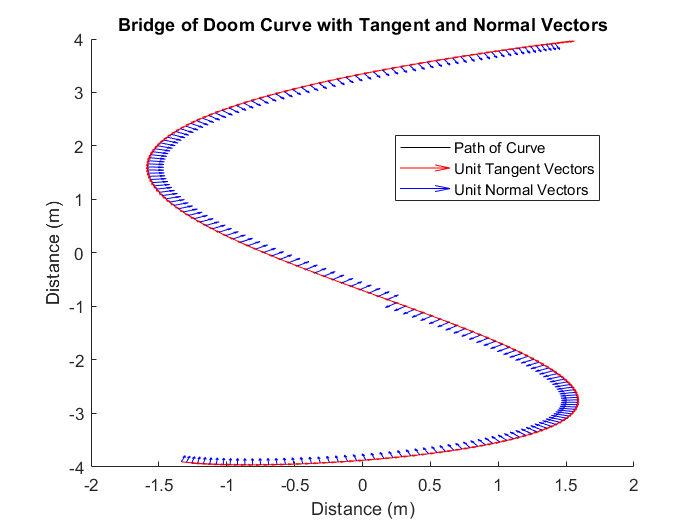


% set the step size and corresponding u-values for plotting the vectors
h_ex = 3.2/Npoints;
u_ex = (0:h_ex:3.2);

% creating the position vector with just the points for each vector
x_ex = 4.*(0.3960.*cos(2.65.*(u_ex + 1.4)));
y_ex = 4.*-0.99.*sin(u_ex + 1.4);
r_ex = [x_ex; y_ex];


% create the velocity vector, the derivative of r
dr_ex = [[diff(x_ex) ./ h_ex, 0]; [diff(y_ex) ./ h_ex, 0]];
% create the unit tangent vectors
T_ex = (dr_ex ./ (sqrt((dr_ex(1,:)).^2 + (dr_ex(2,:)).^2)));
% create the x- and y-compenents of the unit tangent vectors
T_x_ex = T_ex(1,:);
T_y_ex = T_ex(2,:);
% plot the unit tangent vectors in red
quiver(x_ex,y_ex,T_x_ex, T_y_ex, 0.2, 'r')


% create the T prime vector, the derivative of T
dT_ex = [[diff(T_x_ex) ./ h_ex, 0]; [diff(T_y_ex) ./ h_ex, 0]];
% create the unit normal vectors
N_ex = (dT_ex ./ (sqrt((dT_ex(1,:)).^2 + (dT_ex(2,:)).^2)));
% create the x and y-compenents of the unit normal vectors
N_x_ex = N_ex(1,:);
N_y_ex = N_ex(2,:);
% plot the unit normal vectors in blue
quiver(x_ex,y_ex,N_x_ex, N_y_ex, 0.2, 'b')

legend({'Path of Curve','Unit Tangent Vectors','Unit Normal Vectors'}, 'Location', 'best')
hold off

## Actual Bridge of Doom (based on Encoder Data)

% set the step size
h = 15;
% set the distance between the two wheels
d = 0.235;
% import the downloaded encoder data
encoder_data = csvread('my_data (1).csv');
% put the three columns into their owen vectors
times = encoder_data(24:178,1);
left_pos = encoder_data(24:178,2);
right_pos = encoder_data(24:178,3);

% calculate the left and right wheel velocities
left_vel = diff(left_pos) ./ diff(times);
right_vel = diff(right_pos) ./ diff(times);

% calculate the delta times
delta_times = diff(times);

% calculate the linear speed and the angular velocity using the wheel
% velocities
lin_speed_actual = (left_vel + right_vel) ./ 2;
ang_vel_actual = (right_vel - left_vel) ./ d;
% crete place holder x, y, and theta vectors with the initial theoretical
% values as the first values of each list
x_actual = [-1.3349; zeros(154,1)];
y_actual = [-3.9024; zeros(154,1)];
theta_actual = [-0.27534; zeros(154,1)];

% populate the x, y, and theta vectors with the real, calculated values
for n = 1:154
    x_actual(n+1) = x_actual(n) + (lin_speed_actual(n)*cos(theta_actual(n))*delta_times(n));
    y_actual(n+1) = y_actual(n) + (lin_speed_actual(n)*sin(theta_actual(n))*delta_times(n));
    theta_actual(n+1) = theta_actual(n) + (ang_vel_actual(n)*delta_times(n));
end


## Excercise 21.2

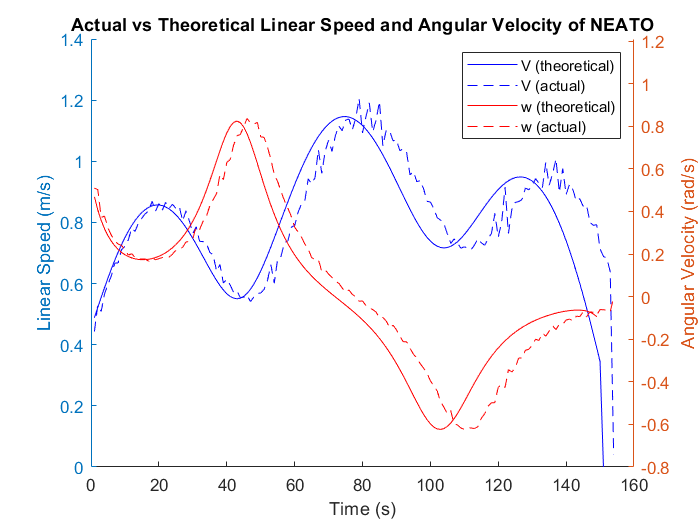

% set the step size
h_2 = 3.2/150;

% set the distance between the two wheels
d = 0.235;

% set the u-values
u = (0:h_2:3.2);

% create the postition vector r for the Bridge of Doom
x = 4.*(0.3960.*cos(2.65.*(u + 1.4)));
y = 4.*-0.99.*sin(u + 1.4);
z = 0 * u;
r = [x; y; z];

% create the velocity vector, the derivative of r
dr = [[diff(x) ./ h_2, 0]; [diff(y) ./ h_2, 0]; [diff(z) ./ h_2, 0]];

% create the linear speed vectors, the magnitudes of the velocity vectors
lin_speed = sqrt((dr(1,:)).^2 + (dr(2,:)).^2 + (dr(3,:)).^2);

% create the unit tangent vectors
T= (dr ./ (sqrt((dr(1,:)).^2 + (dr(2,:)).^2 + (dr(3,:)).^2)));
% create the x-, y-, and z-compenents of the unit tangent vectors
T_x = T(1,:);
T_y = T(2,:);
T_z = T(3,:);

% create the T prime vector, the derivative of T
dT = [[diff(T_x) ./ h_2, 0]; [diff(T_y) ./ h_2, 0]; [diff(T_z) ./ h_2, 0] ];
% create the x-, y-, and z-compenents of the tangent prime vectors
dT_x = dT(1,:);
dT_y = dT(2,:);
dT_z = dT(3,:);

% calculate the theoretical angular velocity
ang_vel = cross(T, dT);


clf
hold on
% plot the theoretical and exerimental linear speeds along the left y-axis
yyaxis left
plot(0.2 * lin_speed, 'b')
plot(lin_speed_actual, 'b--')
ylabel('Linear Speed (m/s)')
% plot the theoretical and experimental angular velocities along the right
% y-axis
yyaxis right
plot(0.2 * (ang_vel(3, :)), 'r')
plot(ang_vel_actual, 'r--')
ylabel('Angular Velocity (rad/s)')
hold off

title('Actual vs Theoretical Linear Speed and Angular Velocity of NEATO')
xlim([0 160])
ylim([-0.80 1.21])
legend({'V (theoretical)','V (actual)','w (theoretical)','w (actual)'})
xlabel('Time (s)')

## Excercise 21.3

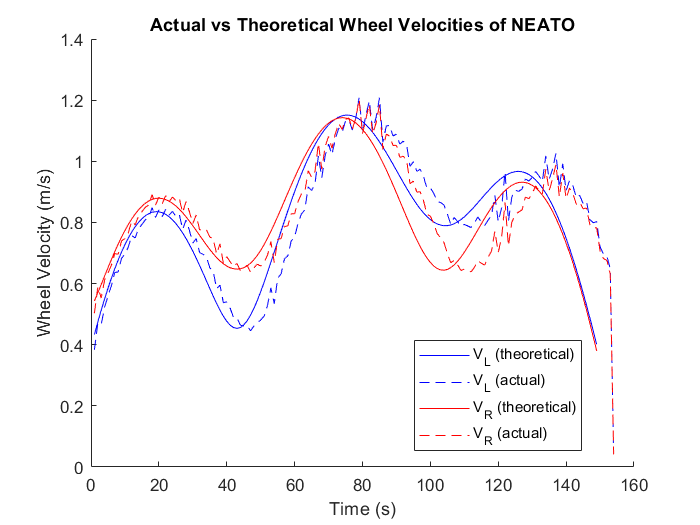

% calculate the theoretical left and right wheel velocities of the NEATO
V_L = lin_speed - (ang_vel(3,:) .* (d /2));
V_R = lin_speed + (ang_vel(3,:) .* (d /2));

clf
hold on
% plot the theoretical and experimental left wheel velocities on the left
% y-axis
plot(0.2 * V_L, 'b')
plot(left_vel, 'b--')
% plot the theoretical and experimental right wheel velocities on the right
% y-axis
plot(0.2 * V_R, 'r')
plot(right_vel, 'r--')
hold off

title('Actual vs Theoretical Wheel Velocities of NEATO')
legend({'V_L (theoretical)','V_L (actual)','V_R (theoretical)','V_R (actual)'}, 'Location','best')
xlabel('Time (s)')
ylabel('Wheel Velocity (m/s)')

## Exercise 21.5

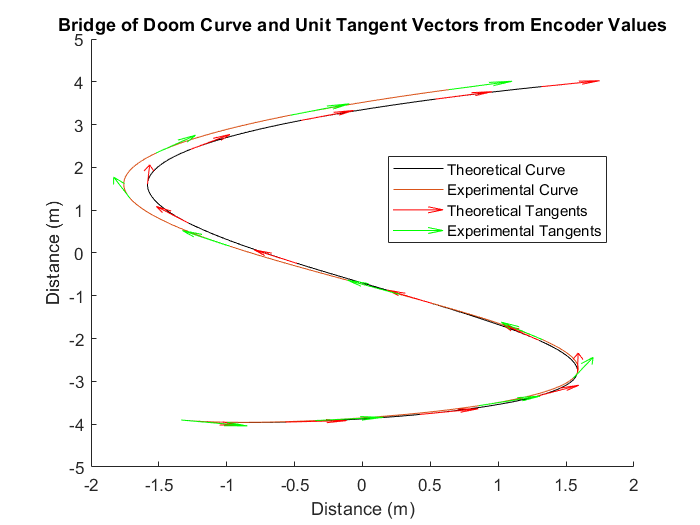

clf
hold on

% plot the experimental and the theoretical curves of the Bridge of Doom
plot(x, y,'k')
plot(x_actual, y_actual)

% create the velocity vector, the derivativeof the experimental position vector
d_pos = [[diff(x_actual) ./ h; 0], [diff(y_actual) ./ h; 0]];

% create the unit tangent vectors for each time
T_actual = (d_pos ./ (sqrt((d_pos(:, 1)).^2 + (d_pos(:, 2)).^2)));
% create the x- and y- components of the unit tangent vectors
Tx_actual = T_actual(:, 1);
Ty_actual = T_actual(:, 2);

% create the derivatives of the unit tangent vectors
dT_actual = [[diff(Tx_actual) ./ h; 0], [diff(Ty_actual) ./ h; 0]];
% plot the theoretical vectors
quiver(x_ex(1:h:end),y_ex(1:h:end),T_x_ex(1:h:end), T_y_ex(1:h:end), 0.2, 'r')

% plot the experimental vectors
quiver(x_actual(1:h:end), y_actual(1:h:end), Tx_actual(1:h:end), Ty_actual(1:h:end), 0.2, 'g')
hold off

title('Bridge of Doom Curve and Unit Tangent Vectors from Encoder Values')
xlabel('Distance (m)')
ylabel('Distance (m)')
legend({'Theoretical Curve','Experimental Curve','Theoretical Tangents','Experimental Tangents'}, 'Location', 'best')